%Load datasaet 
clear;
rng(42);

dataStruct = load("/Users/florinecramer/Documents/MATLAB/brain_computer_project/ass3/BI5_segments_HTS.mat");
segments = dataStruct.segments;
classes = dataStruct.classlabels;

% Randomise and split the classes
idx_non = randperm(sum(classes == 1));
idx_tar = randperm(sum(classes == 2));
non = segments(:,:,classes == 1);
tar = segments(:,:,classes == 2);

tp1 = 21; tp2 = 32;
extract = @(seg, idx, tp) squeeze(seg(2, tp, idx))';

X_train = [extract(non, idx_non(1:900),tp1),extract(tar,idx_tar(1:200),tp1); ...
           extract(non, idx_non(1:900),tp2),extract(tar,idx_tar(1:200),tp2)];
Y_train = [-ones(1,900), ones(1,200)];

%% 10 fold 10 cv validation of the LDA classifier
X_all = X_train;
Y_all = Y_train;

num_repetitions = 10;
num_folds= 10;
all_accuracies= zeros(num_repetitions, num_folds);

for rep = 1:num_repetitions
    indices = crossvalind('Kfold', Y_all, num_folds);
    for fold = 1:num_folds
        test_idx  = (indices == fold);
        train_idx = ~test_idx;

        [~, ~, w_cv, b_cv, ~] = custom_LDA( ...
            X_all(:,train_idx), Y_all(train_idx), ...
            X_all(:,test_idx),  Y_all(test_idx));

        preds = sign(w_cv' * X_all(:,test_idx) + b_cv);
        acc_non = mean(preds(Y_all(test_idx) == -1) == -1);
        acc_tar = mean(preds(Y_all(test_idx) ==  1) ==  1);
        all_accuracies(rep, fold) = 0.5 * acc_non + 0.5 * acc_tar;
    end
end

Test Set Accuracy: 83.64%
Train Set Accuracy: 82.32%
Test Set Accuracy: 81.82%
Train Set Accuracy: 82.32%
Test Set Accuracy: 83.64%
Train Set Accuracy: 82.12%
Test Set Accuracy: 82.73%
Train Set Accuracy: 82.32%
Test Set Accuracy: 80.00%
Train Set Accuracy: 82.83%
Test Set Accuracy: 81.82%
Train Set Accuracy: 82.53%
Test Set Accuracy: 83.64%
Train Set Accuracy: 81.92%
Test Set Accuracy: 81.82%
Train Set Accuracy: 82.12%
Test Set Accuracy: 80.00%
Train Set Accuracy: 82.93%
Test Set Accuracy: 80.91%
Train Set Accuracy: 82.32%
Test Set Accuracy: 80.91%
Train Set Accuracy: 82.22%
Test Set Accuracy: 81.82%
Train Set Accuracy: 82.12%
Test Set Accuracy: 82.73%
Train Set Accuracy: 82.63%
Test Set Accuracy: 82.73%
Train Set Accuracy: 82.53%
Test Set Accuracy: 82.73%
Train Set Accuracy: 82.63%
Test Set Accuracy: 82.73%
Train Set Accuracy: 82.22%
Test Set Accuracy: 80.00%
Train Set Accuracy: 82.73%
Test Set Accuracy: 83.64%
Train Set Accuracy: 82.02%
Test Set Accuracy: 81.82%
Train Set Accuracy: 

mean_cv = mean(all_accuracies(:));
std_cv= std(all_accuracies(:));

fprintf('\n--- EEG 10x10-fold Cross-validation Results ---\n');


--- EEG 10x10-fold Cross-validation Results ---


fprintf('Mean CV Balanced accuracy : %.2f%%\n', mean_cv * 100);

Mean CV Balanced accuracy : 53.95%


fprintf('Std CV Accuracy: %.2f%%\n', std_cv  * 100);

Std CV Accuracy: 3.10%


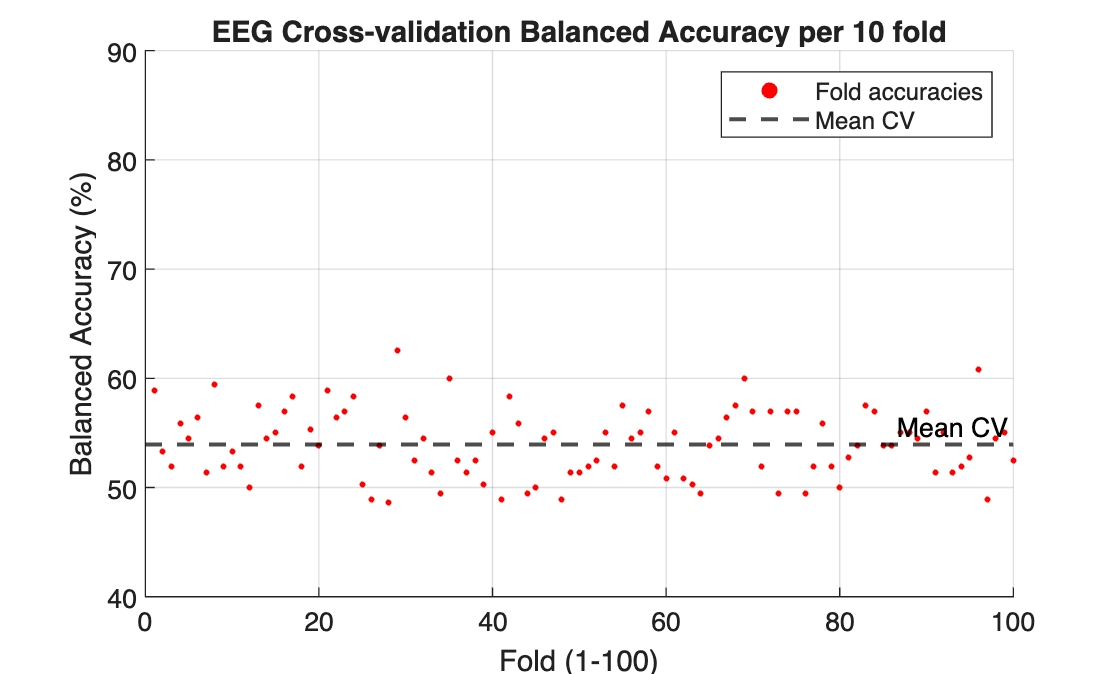


figure;
scatter(1:100, all_accuracies(:)' * 100, 5, 'red', 'filled');
yline(mean_cv * 100, '--', 'LineWidth', 1.5, 'Color', 'black', 'Label', 'Mean CV');
title('EEG Cross-validation Balanced Accuracy per 10 fold');
xlabel('Fold (1-100)');
ylabel('Balanced Accuracy (%)');
ylim([40 90]);
grid on;
legend('Fold accuracies', 'Mean CV');